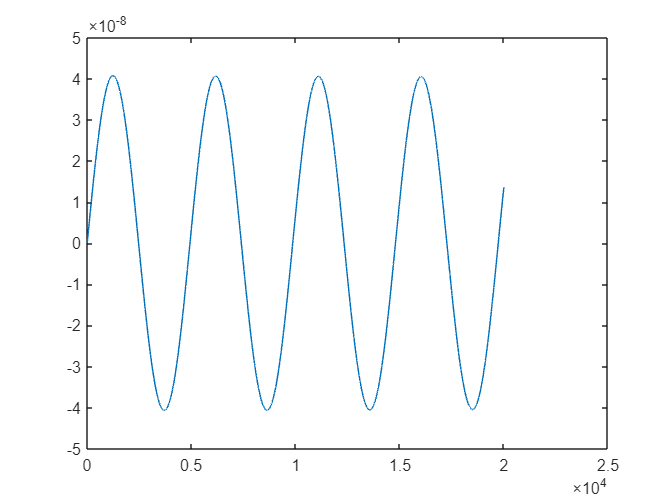

%实际模拟其振动周期（中心粒子只受周围6个固定粒子作用时）

a=1.6*10^(-6);
a00=-0.02*a; a1=-a; a2=-0.5*a; a3=-0.5*a; a4=0.5*a; a5=0.5*a; a6=a; 
b00=0; b1=0; b2=0.5*sqrt(3)*a; b3=-0.5*sqrt(3)*a; b4=0.5*sqrt(3)*a; b5=-0.5*sqrt(3)*a; b6=0;
k1=510; c6=7280*1.6*10^(-19); c5=c6; c4=c5; c3=c4; c2=c3; c1=c2; c00=c1;m=6.13*10^(-13);dt=0.001;s=0;
tsx=zeros(1,2001);tsvx=zeros(1,2001);
%初始条件
vx00=0;
fxfl(a1,a00,b1,b00,k1,c1,c00);
fxfl(a2,a00,b2,b00,k1,c2,c00);
fxfl(a3,a00,b3,b00,k1,c3,c00);
fxfl(a4,a00,b4,b00,k1,c4,c00);
fxfl(a5,a00,b5,b00,k1,c5,c00);
fxfl(a6,a00,b6,b00,k1,c6,c00);
fxx=fxfl(a1,a00,b1,b00,k1,c1,c00)+fxfl(a2,a00,b2,b00,k1,c2,c00)+fxfl(a3,a00,b3,b00,k1,c3,c00)+fxfl(a4,a00,b4,b00,k1,c4,c00)+fxfl(a5,a00,b5,b00,k1,c5,c00)+fxfl(a6,a00,b6,b00,k1,c6,c00);
for t=0:dt:20
    at00=a00;
    vxt00=vx00;


  vx00=vxnn(at00,a1,a2,a3,a4,a5,a6,b00,b1,b2,b3,b4,b5,b6,vxt00,0,0,0,0,0,0,0,0,0,0,0,0,0,dt,k1,c00,c1,c2,c3,c4,c5,c6,m);
  [a00,~,~,~,~]=xlg(at00,vx00,dt);
  s=s+1;
  tsx(1,s)=a00;tsvx(1,s)=vx00;


end
tsx;tsvx;
figure(1)
plot(tsvx)